cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('rate_EMCLs')
load('transducer_2board')

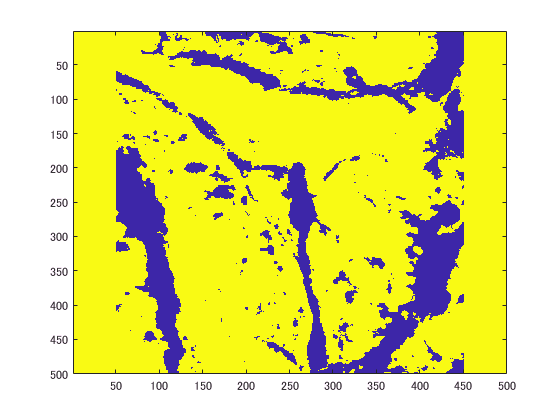

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_08_10_realisticScatter');
load('case1')
figure;
imagesc(medium.sound_speed);

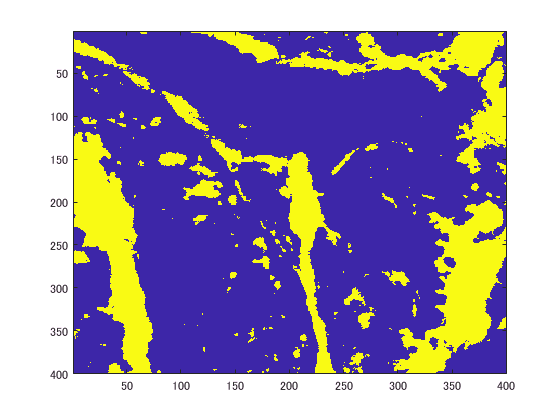

a = medium.sound_speed(51:450,51:450);
b = (a == min(min(a)));
imagesc(b);

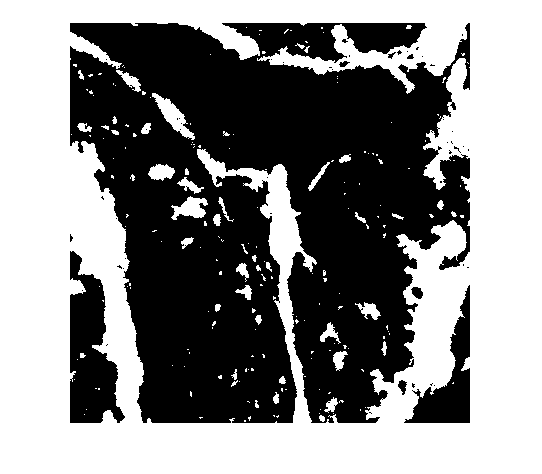

lbl = bwlabel(b);
bw = logical(b);
nLabels = max(lbl(:));
rgb = label2rgb(lbl, jet(nLabels), 'w', 'shuffle');
imshow(bw);

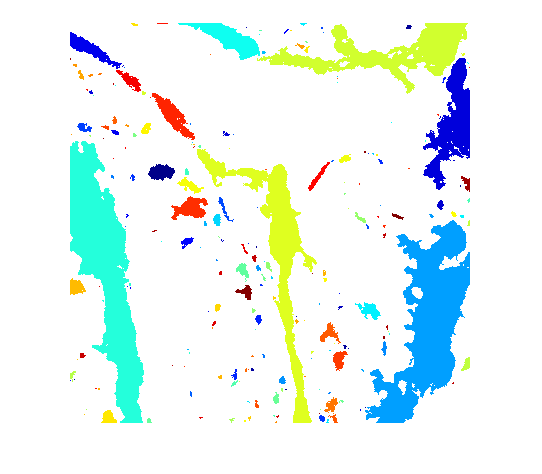

imshow(rgb)

s  = regionprops(bw);